# figureの作成

脳波の波形を描いていきます。

dataは(ch,time,epoch,freq,prt); の構造です。

練習として，参加者一人目，1010条件，１epoch目，1チャンネルの波形を書いていきます。

つまり，prt=1, freq=1, epoch=1, ch=1の波形

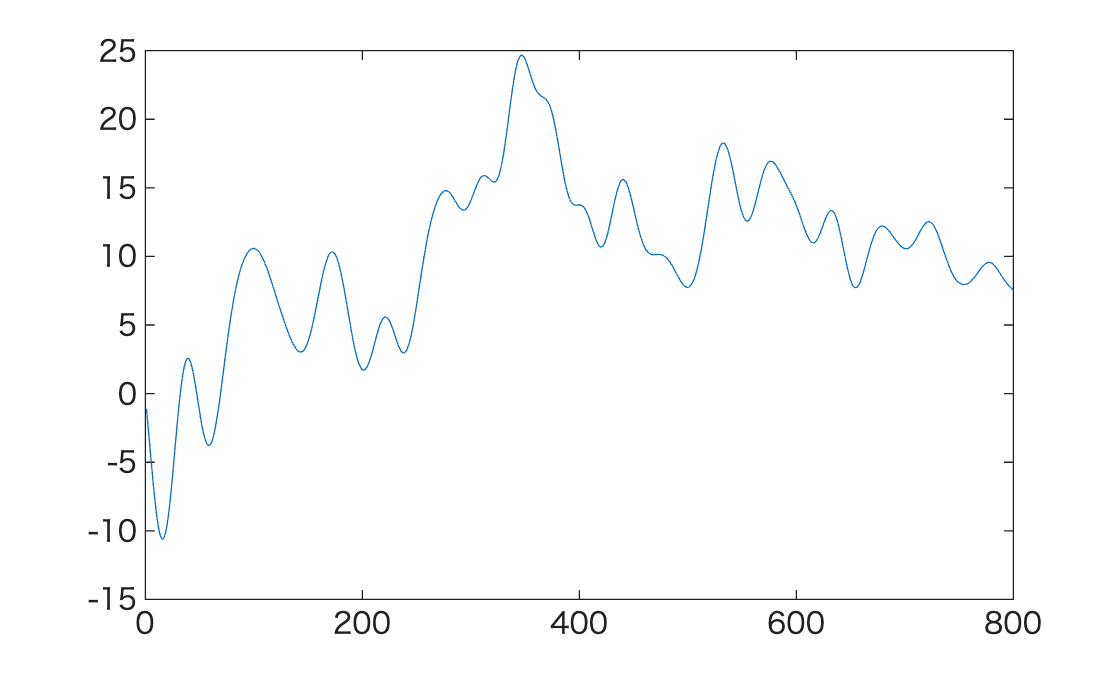

figure
plot(data(1,:,1,1,1))

% ↑これでもよいが横軸と縦軸を脳波研究で慣習的な表示に変更していきます。

横軸（時間軸）は0から800となっていますが，100msのベースラインを切り出しているので，-100から開始したい。

縦軸（amplitude）は脳波では上が負（-），下が正(+)なので符号を逆にしたい。

## 関数の説明 plot -> 線形 2 次元プロット

Yのサイズが1000*1の場合，

plot(Y)とすると，ｘの値は，1～1000の値とそれに対応するＹの値の 2 次元のライン プロットを作成します。

一方，plot(X,Y) とも書けて、X の値に対応する Y のデータの 2 次元ライン プロットを作成します。

ただし，XとYは同じ長さでなければなりません。

## 関数の説明 linspace -> 線形に等間隔なベクトルを作成

% y = linspace(x1,x2) は、x1 ～ x2 の間の等間隔の点を 100 個含む行ベクトルを返します。
y1 = linspace(-0.1,0.7);
% y = linspace(x1,x2,n) は、n 個の点を出力します。点の間隔は (x2-x1)/(n-1) です。
y2 = linspace(-0.1,0.7,1000);

これを踏まえて以下の様にplotしていきます

## linspaceを使ってfigureの作成

参加者一人目，1010条件，１epoch目，1チャンネルの波形なので，

prt=1, freq=1, epoch=1, ch=1

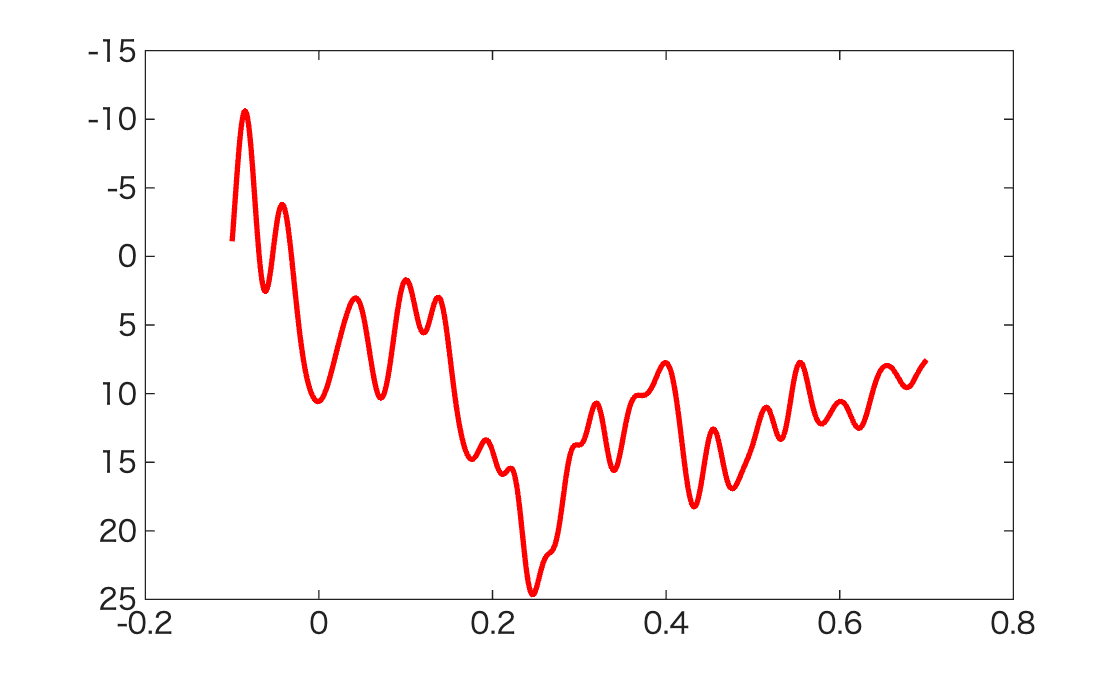

fs = 1000; % サンプリング周波数
N=size(data,2); % データ長

x=linspace(-0.1,(N-100)/fs,N);
y=data(1,:,1,1,1); % (ch,time,epoch,freq,prt); 
figure
plot(x,y,'r','LineWidth',2); % 'r'は赤い色の指定，'LineWidth'は線の太さを指定
axis('ij') % y 値のプラスマイナスを逆にします。

% ------------------------------------------------